clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref



% param.ctrl.ks(:,:,1) =[-0.0669, 0.3820, 0.0769];
% param.ctrl.ks(:,:,2) = [-0.0390, 0.2228, 0.0449];
% param.ctrl.ks(:,:,3) = [-0.0334, 0.1910, 0.0385];
% param.ctrl.ks(:,:,4) =[-0.0557,0.3184, 0.0641];

simtime = 10*60;

## Control

param.ctrl.Ks = control.DesignProcedure1(param,0);

Evaluation of design procedure 1 
cali_Q is positive definite


ans =     0.6343    0.6385    0.6433    0.6459    0.9608    0.9724    0.9983    1.0104    1.6736    1.6773    1.6924    1.6982


cali_R is positive definite


ans = 1.0e-08 *

    0.0011    0.0015    0.0028    0.0036    0.0119    0.0143    0.0244    0.0307    0.1656    0.2062    0.3793    0.6340


Tau is found to be:


ans = -2.6605e-14

Eigenvalues of the decoupled systems are all negative 


ans =   -0.5340 + 3.3908i  -0.5340 - 3.3908i  -0.3426 + 0.0000i  -0.5276 + 3.4206i  -0.5276 - 3.4206i  -0.3429 + 0.0000i  -0.5260 + 3.3948i  -0.5260 - 3.3948i  -0.3430 + 0.0000i  -0.5319 + 3.3913i  -0.5319 - 3.3913i  -0.3427 + 0.0000i


Eigenvalues of the coupled systems are all negative 


ans =   -1.0053 + 5.3915i  -1.0053 - 5.3915i  -0.9139 + 4.9989i  -0.9139 - 4.9989i  -0.6350 + 3.8674i  -0.6350 - 3.8674i  -0.7520 + 4.3499i  -0.7520 - 4.3499i  -0.3392 + 0.0000i  -0.3399 + 0.0000i  -0.3419 + 0.0000i  -0.3411 + 0.0000i


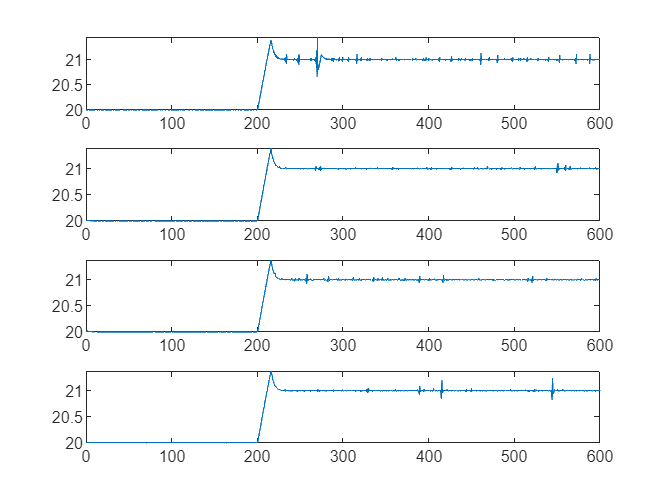

for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode45(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);
end
figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15)
end

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0,options);

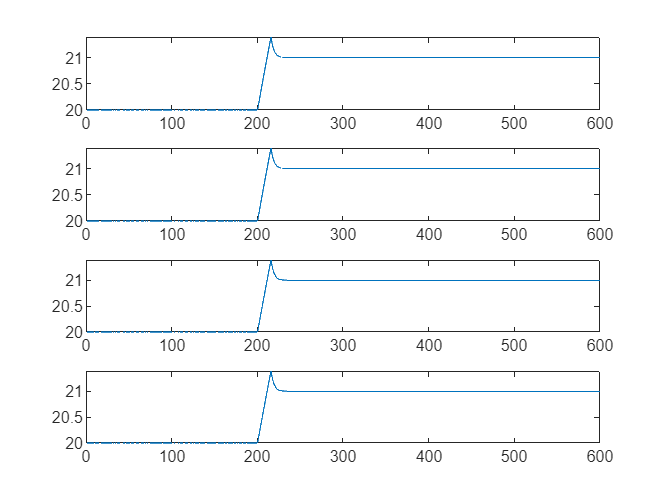

coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(coupledResults.time,coupledResults.Ta(:,1)-273.15)
end